clear
global N K

K=8; % number of clusters
N = 20; %number of MFCC features to use;
distortion_eps = 0.05;

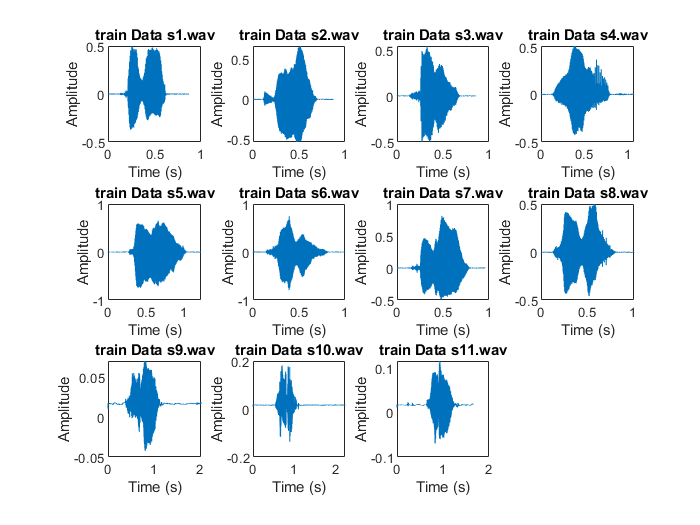

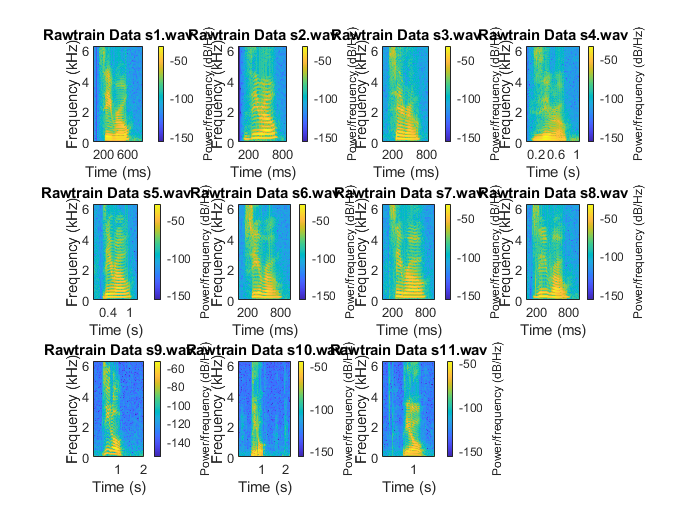

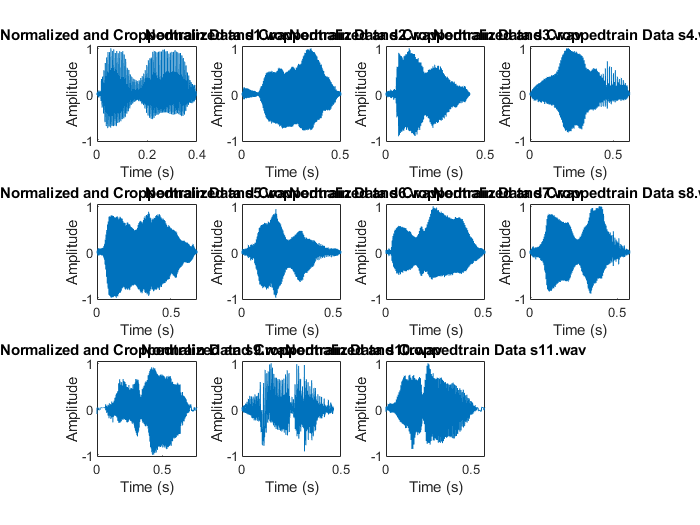

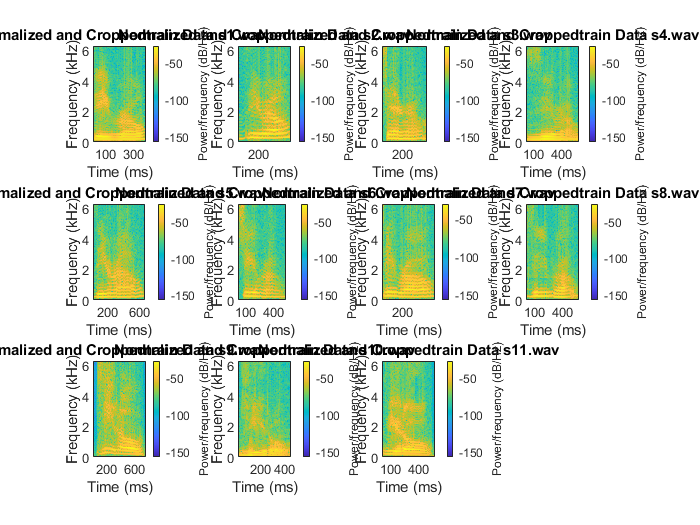

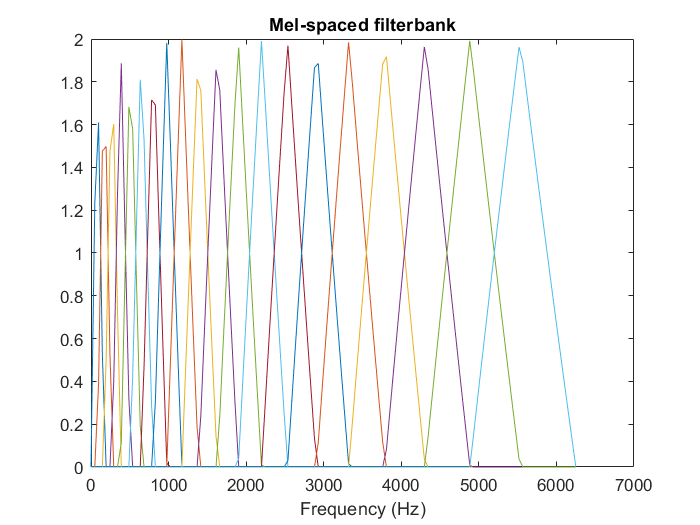

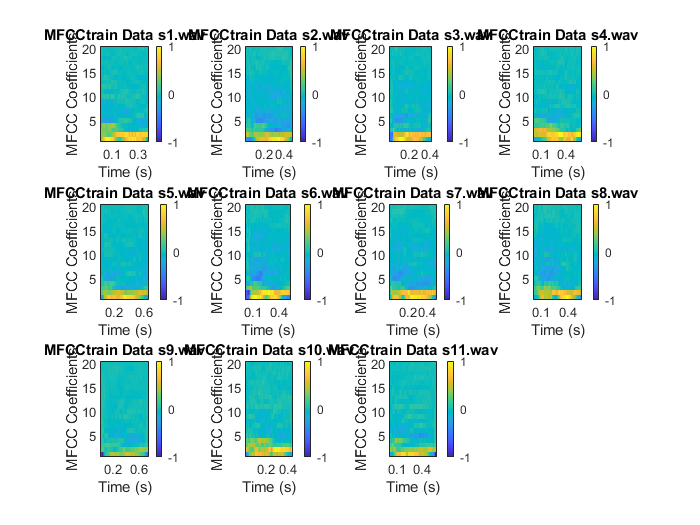

cepstrum = 1×11 cell array
    {20×56 double}    {20×72 double}    {20×60 double}    {20×86 double}    {20×97 double}    {20×78 double}    {20×73 double}    {20×82 double}    {20×110 double}    {20×65 double}    {20×83 double}


t_out = 1×11 cell array
    {1×56 double}    {1×72 double}    {1×60 double}    {1×86 double}    {1×97 double}    {1×78 double}    {1×73 double}    {1×82 double}    {1×110 double}    {1×65 double}    {1×83 double}


% %% Train
% [cepstrum, t_out] = mfcc('train', 256, 20)

% %% Determine Centroid
% for i=1:size(cepstrum,2)
%     [codebook{i}, clusterID{i}, D{i}] = LBG((cepstrum{i}(1:N,:))', K, distortion_eps);
% end
% save codebook.mat codebook

%%% Test
% Load Ground Truth
T = readtable('./Data/Test_data/ground_truth.csv');

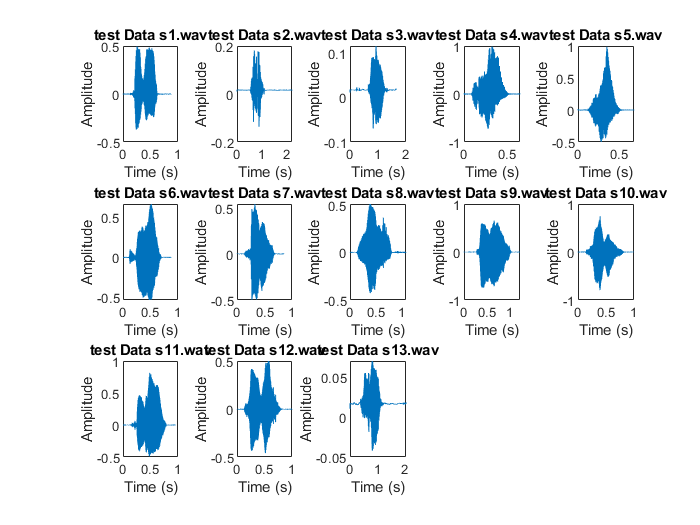

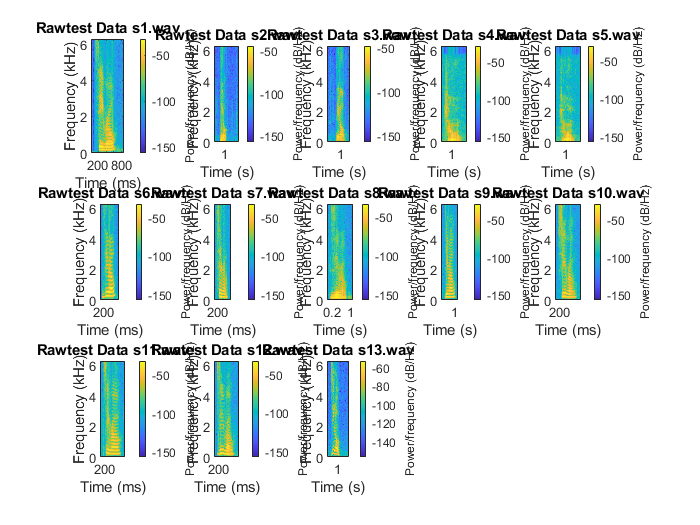

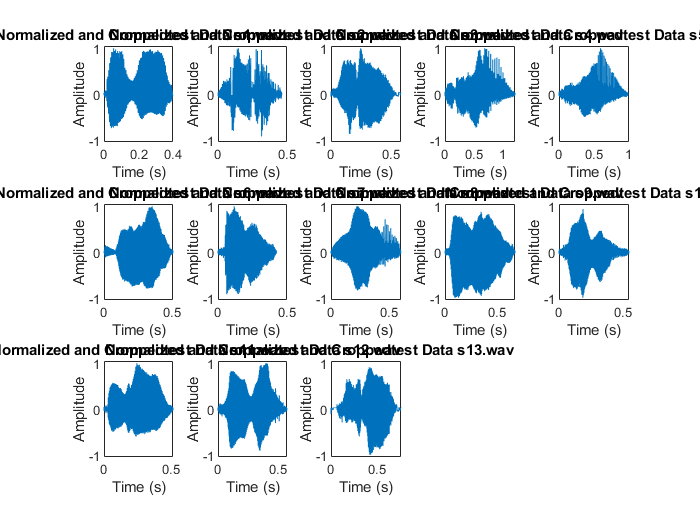

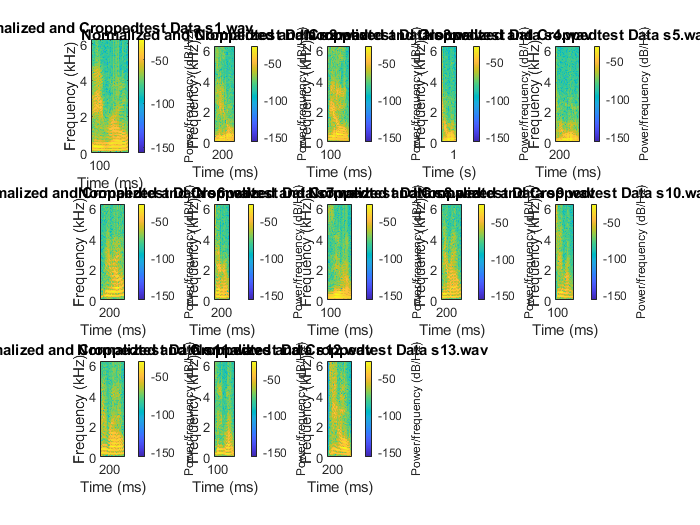

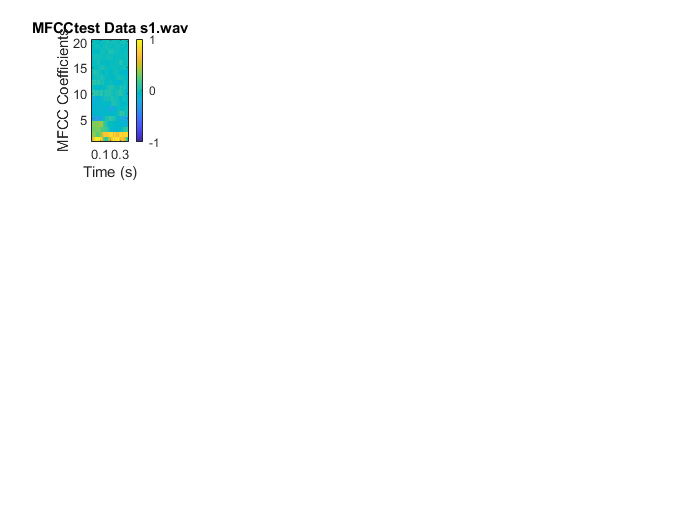

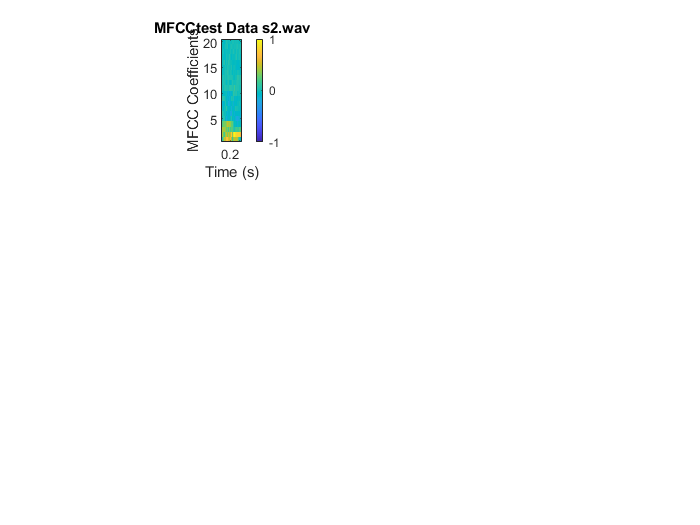

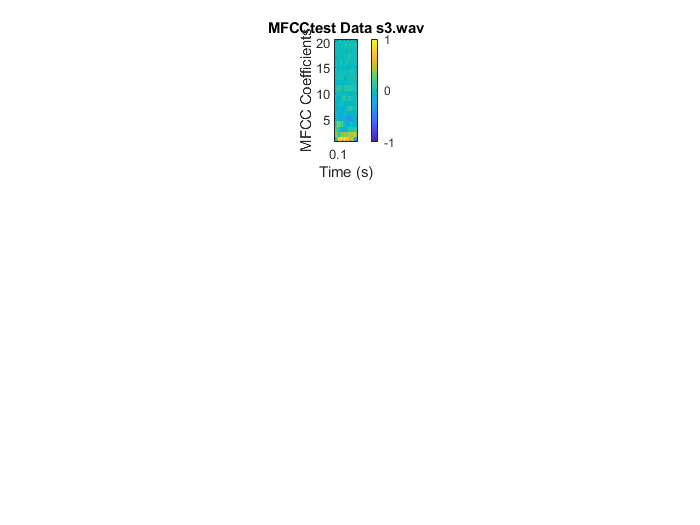

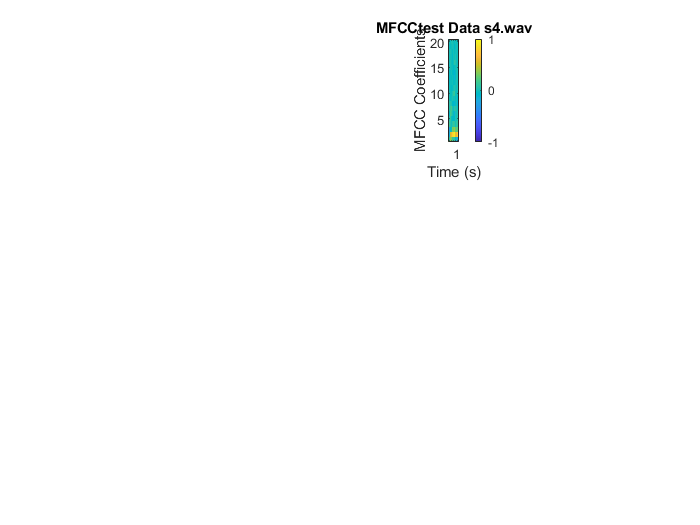

ground_truth = T.("ground_truth");
[cepstrum,t] = mfcc('test',256,20);

%
for i=1:size(cepstrum,2)
    [codebook_test{i}, clusterID{i}, D{i}] = LBG((cepstrum{i}(1:N,:))', K, distortion_eps);
end

Unrecognized function or variable 'N'.


total_samples = length(codebook_test);
correct_guess = 0;
for i=1:total_samples
    speaker_estimate = classify(codebook_test{i})
    if (speaker_estimate == ground_truth(i))
        correct_guess = correct_guess + 1;
    end
end

disp(correct_guess/total_samples*100)

